# **三维矢量场的散度演示**

**        对于三维函数，可以用divergence函数取散度，从而得到一个散度函数；使用pcolor函数绘制散度。**

- **定义函数**

syms x y real	
a=6;
b=3;
c=1;
d=-2;
F = [ cos(a*x+b*y), sin(c*x+d*y) ]	

$$F = \left(\begin{array}{cc} \cos\left(6\,x+3\,y\right) & \sin\left(x-2\,y\right) \end{array}\right)$$

- **使用divergence函数取散度**

g = divergence(F,[x y]) %求函数F的散度，符号形式

$$g = -2\,\cos\left(x-2\,y\right)-6\,\sin\left(6\,x+3\,y\right)$$

divF=matlabFunction(g);	%将散度转换为函数形式

- **定义网格**

x=linspace(-2.5,2.5,20);
[X,Y]=meshgrid(x,x);	%定义网格

- **使用pcolor函数绘制散度分布**

div_num=divF(X,Y);	%散度的数值形式
pcolor(X,Y,div_num); 	%绘制散度
shading interp;	%差值
colorbar;	%绘制色条
hold on;	%保持绘图模式打开

- **绘制函数的矢量分布**

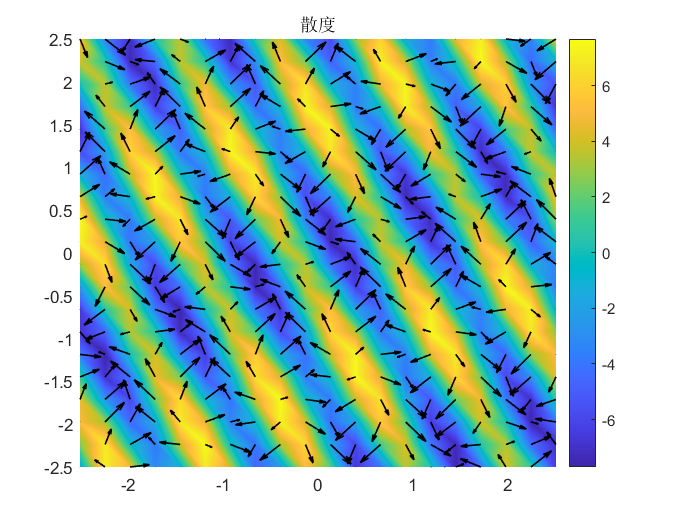

Funcx=matlabFunction(F(1));	%F的x分量
Funcy=matlabFunction(F(2));	%F的y分量
Fx=Funcx(X,Y);
Fy=Funcy(X,Y);
% Fx=cos(X+2*Y);	%F的x分量
% Fy=sin(X-2*Y);	%F的y分量
quiver(X,Y,Fx,Fy,'k','linewidth',1);	%绘制箭头图
title('散度')
set(gcf,'Visible','on');   	    %强制图片弹出输出